General Symbolic Variables

syms g L_1 L_2

Full manipulator dynamics:


$$\begin{array}{l}
M\left(\mathit{\mathbf{q}}\right)\ddot{\mathit{\mathbf{q}}} +C_a \left(\mathit{\mathbf{q}}\right){\dot{\mathit{\mathbf{q}}} }_a +C_b \left(\mathit{\mathbf{q}}\right){\dot{\mathit{\mathbf{q}}} }_b +G\left(\mathit{\mathbf{q}}\right)=\tau \\
\mathit{\mathbf{q}}=\left\lbrack \begin{array}{c}
{\mathit{\mathbf{q}}}_1 \\
\vdots \\
{\mathit{\mathbf{q}}}_n 
\end{array}\right\rbrack ,\;\dot{\mathit{\mathbf{q}}} {\dot{\mathit{\mathbf{q}}} }^{\top } =\left\lbrack \begin{array}{ccc}
{\dot{q} }_1 {\dot{q} }_1  & \cdots  & {\dot{q} }_1 {\dot{q} }_n \\
\vdots  & \ddots  & \vdots \\
{\dot{q} }_n {\dot{q} }_1  & \cdots  & {\dot{q} }_n {\dot{q} }_n 
\end{array}\right\rbrack \\
\;{\dot{\mathit{\mathbf{q}}} }_a =\dot{\mathit{\mathbf{q}}} {\dot{\mathit{\mathbf{q}}} }^{\top } \;\textrm{where}\;\left(i=j\right)\\
\;{\dot{\mathit{\mathbf{q}}} }_b =\dot{\mathit{\mathbf{q}}} {\dot{\mathit{\mathbf{q}}} }^{\top } \;\textrm{where}\;\left(i\not= j\right)-\;\textrm{unique}\;\textrm{terms}\;\textrm{only}
\end{array}$$


$M$ = Mass matrix

$C_a$ = Centripetal matrix

$C_b$ = Coriolis matrix

$G$ = Gravitational matrix

$\tau$ = Generalized torques

Dynamics Derivation For Decoupled Belt Drive

syms L__d_g_1 L__d_g_2 m__d_1 m__d_2 I__d_1 I__d_2 I__d_m_1 n_1 I__d_m_2 n_2
syms psi_1 psi_dot_1 psi_ddot_1 psi_2 psi_dot_2 psi_ddot_2
syms tau__d_1 tau__d_2

q_psi = [psi_1 psi_dot_1 psi_ddot_1; psi_2 psi_dot_2 psi_ddot_2];

r_O_A = L__d_g_1*[cos(psi_1); sin(psi_1);];
r_O_B = L_1*[cos(psi_1); sin(psi_1);];
r_O_C = [L_1*cos(psi_1)+L__d_g_2*cos(psi_2); L_1*sin(psi_1)+L__d_g_2*sin(psi_2);];
r_O_D = [L_1*cos(psi_1)+L_2*cos(psi_2); L_1*sin(psi_1)+L_2*sin(psi_2);];

omega_1 = [0; 0; psi_dot_1];
V_A = cross_2d(omega_1,r_O_A);
omega_2 = [0; 0; psi_dot_2];
V_C = cross_2d(omega_1,r_O_B) + cross_2d(omega_2,r_O_C-r_O_B);

V_A_mag_sq = mag_2d(V_A)^2;
V_C_mag_sq = mag_2d(V_C)^2;

V_C_mag_sq = simplify(expand(V_C_mag_sq));

T_trans = 1/2*m__d_1*V_A_mag_sq + 1/2*m__d_2*V_C_mag_sq;
T_rot = 1/2*I__d_1*psi_dot_1^2 + 1/2*I__d_2*psi_dot_2^2 + 1/2*I__d_m_1*(n_1*psi_dot_1)^2 + 1/2*I__d_m_2*(n_2*psi_dot_2)^2;
T = T_trans + T_rot;
T_trans*2
T_rot*2
V = m__d_1*g*L__d_g_1*sin(psi_1) + m__d_2*g*(L_1*sin(psi_1) + L__d_g_2*sin(psi_2))

lagrange_d = T-V;
Q_d = [tau__d_1; tau__d_2];
EOM_d = calc_lagrange(lagrange_d,q_psi,Q_d);
[M_d, Ca_d, Cb_d, G_d] = export_matrices(EOM_d,q_psi)

Dynamics Derivation for Standard Serial Link (Infants leg)

syms L__i_g_1 L__i_g_2 m__i_1 m__i_2 I__i_1 I__i_2
syms theta_1 theta_dot_1 theta_ddot_1 theta_2 theta_dot_2 theta_ddot_2
syms tau__i_1 tau__i_2

q_theta = [theta_1 theta_dot_1 theta_ddot_1; theta_2 theta_dot_2 theta_ddot_2];

r_O_A = L__i_g_1*[cos(theta_1); sin(theta_1);];
r_O_B = L_1*[cos(theta_1); sin(theta_1);];

omega_1 = [0; 0; theta_dot_1];
V_A = cross_2d(omega_1,r_O_A);

J_C = [-L_1*sin(theta_1)-L__i_g_2*sin(theta_1+theta_2) -L__i_g_2*sin(theta_1+theta_2);
       L_1*cos(theta_1)+L__i_g_2*cos(theta_1+theta_2) L__i_g_2*cos(theta_1+theta_2)];
V_C = J_C*[theta_dot_1; theta_dot_2];

V_A_mag_sq = mag_2d(V_A)^2;
V_C_mag_sq = mag_2d(V_C)^2;

V_C_mag_sq = simplify(expand(V_C_mag_sq));

T_trans = 1/2*m__i_1*V_A_mag_sq + 1/2*m__i_2*V_C_mag_sq;
T_rot = 1/2*I__i_1*theta_dot_1^2 + 1/2*I__i_2*(theta_dot_1+theta_dot_2)^2;
T = T_trans + T_rot;
T_trans
T_trans2x = (L__i_g_1^2*m__i_1*theta_dot_1^2) + m__i_2*((L_1^2+L__i_g_2^2)*theta_dot_1^2 + 2*cos(theta_2)*L_1*L__i_g_2*(theta_dot_1^2+theta_dot_1*theta_dot_2)+L__i_g_2^2*(2*theta_dot_1*theta_dot_2 + theta_dot_2^2))

T_rot
V = m__i_1*g*L__i_g_1*sin(theta_1) + m__i_2*g*(L_1*sin(theta_1) + L__i_g_2*sin(theta_1+theta_2))

lagrange_i = T-V;
Q_i = [tau__i_1; tau__i_2];
EOM_i = calc_lagrange(lagrange_i,q_theta,Q_i)
[M_i, Ca_i, Cb_i, G_i] = export_matrices(EOM_i,q_theta)

Combine full system (Device + Infant Leg) by converting theta to psi for the infant EOM

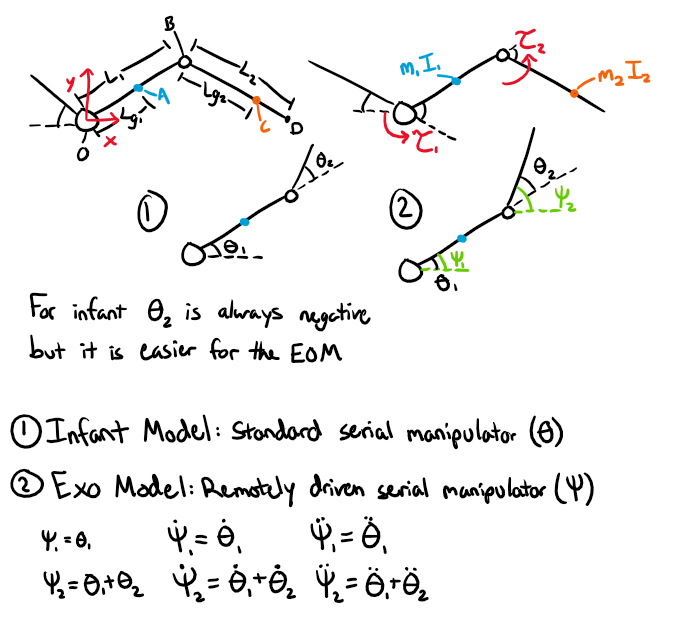

theta_vars = [theta_1 theta_2...
              theta_dot_1 theta_dot_2...
              theta_ddot_1 theta_ddot_2];

psi_vars = [psi_1 psi_2-psi_1...
            psi_dot_1 psi_dot_2-psi_dot_1...
            psi_ddot_1 psi_ddot_2-psi_ddot_1];

EOM_i_psi = subs(EOM_i,theta_vars,psi_vars);
[M_i_psi, Ca_i_psi, Cb_i_psi, G_i_psi] = export_matrices(EOM_i_psi,q_psi)

EOM_d;
EOM_i;
EOM_i_psi;
EOM_full = EOM_i_psi + EOM_d
[M_f, Ca_f, Cb_f, G_f] = export_matrices(EOM_full,q_psi)

tau_M = M_f*[psi_ddot_1; psi_ddot_2];
tau_C = Ca_f*[psi_dot_1^2; psi_dot_2^2];
tau_G = G_f;
tau_total = tau_M + tau_C + tau_G == [tau__d_1 + tau__i_1; tau__d_2 + tau__i_2];
simplify(expand(simplify(EOM_full)) - expand(simplify(tau_total)))